# **Image Segmentation**

**slide 697 - 700**

**“Pixel-based” **is the simplest approach. It separates the pixels of an image into different segments** by thresholding.**

**Thresholding** is used to extract an object from its background by assigning an intensity value for each pixel such that each pixel is either classified as an object point or a background point 

When the modes of histogram can be clearly distinguished, each mode represents either the background or an object

**The success of intensity thresholding is related to the width and depth of the valley(s) separating the histogram modes.**

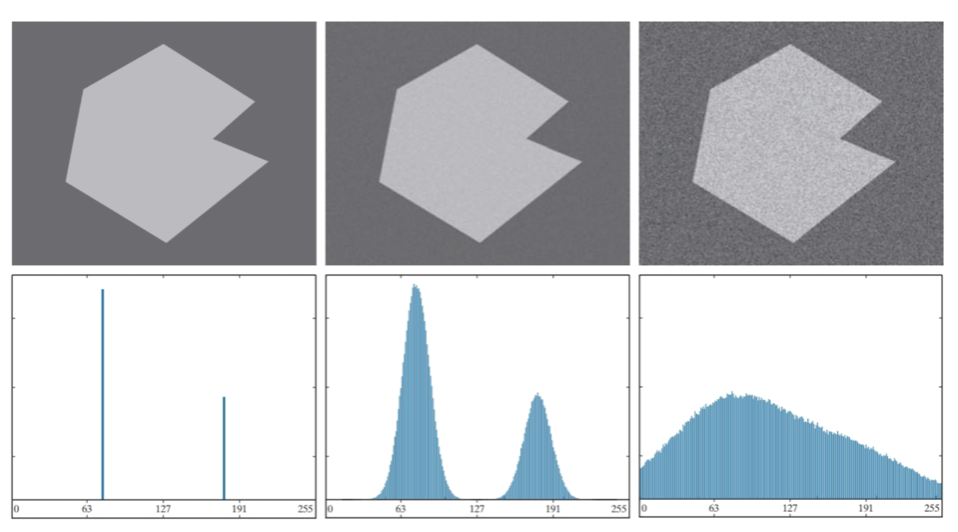

(1) the separation between peaks (the further apart the peaks are, the better the chances of separating the modes); 

(2) the noise content in the image (the modes broaden as noise increases); 

(3) the relative sizes of objects and background; 

(4) the uniformity of the illumination source; 

(5) the uniformity of the reflectance properties of the image.

example of not uniform illumination: add a gray level ramp.

clear
close all
a=imread('Fig1036b.tif');
subplot(2,3,1)
imshow(a)
colormap(gray(255))
title('input image')
subplot(2,3,4)
imhist(a)
b=imread('ramp.tif');
subplot(2,3,2)
image(b)
colormap(gray(255))
title('gray scale ramp')
subplot(2,3,5)
imhist(b)
c=double(a)+double(b);
d=mat2gray(c);
subplot(2,3,3)
imagesc(c)
colormap(gray(255))
title('input image + ramp')
subplot(2,3,6)
imhist((d))
%
figure
T2 = 0.2;
BW = imbinarize(d,T2);
imshow(BW)

**Thresholding**

An **automated procedure for bimodal histograms**:

- **Select an initial estimate of the threshold T. **A good initial value is the average intensity of the image.

- **Partition the image into two groups, R1, R2 , **using the threshold T.

- **Calculate the mean grey values     and     of the partitions, R1, R2.**

- **Select a new threshold: **

- **Repeat steps 2-4 until the threshold value in successive iterations do not change **(is smaller than a predefined parameter)

clear
close all
f=imread('fingerprint.tif');
f=im2double(f);
T1 = mean(f(:));
done =  false;
while  ~  done
  g = f >= T1;
TNext = 0.5*(mean(f(g))+mean(f( ~g)));
done = abs(T1 - TNext) < 0.5;
T1=TNext;
end
BW = imbinarize(f,TNext);
imshowpair(f,BW,'montage')

**Matlab function**

**graythresh** - Global image threshold using Otsu's method

chooses the threshold to minimize the intraclass variance

**T2 = graythresh(f);**

exercise: 

open image 'fingerprint.tif'

Thresholding and compare an image using T1 and T2

clear
close all
f=imread('fingerprint.tif');
f=im2double(f);
T2 = graythresh(f);
BW = imbinarize(f,T2);
% T1
T1 = mean(f(:));
done =  false;
while  ~  done
  g = f >= T1;
TNext = 0.5*(mean(f(g))+mean(f( ~g)));
done = abs(T1 - TNext) < 0.5;
T1=TNext;
end
BWT1 = imbinarize(f,TNext);
imshowpair(BWT1,BW,'montage')

**Otsu’s thresholding slide 713 - 718**

The algorithm works on  bimodal histogram image, it calculates the optimum threshold separating the two classes so that their combined spread (intra-class variance) is minimal, or equivalently so that their inter-class variance is maximal.

The 'Within-Class Variance’ is simply the sum of the two variances multiplied by their associated weights.

Otsu's thresholding method involves iterating through all the possible threshold values to find the threshold value where the sum of foreground and background spreads is at its minimum.

**Exercise**: 

**segment the molecules from the background in polymersomes.tif**

clear
close all
a=imread('polymersomes.tif');
imshow(a)
figure
imhist(a)
axis([-10 260 0 1000])
a=double(a);
T1 = mean2(a);
BW = imbinarize(a,T1);
B=BW*255;
figure
image(B)
title('threshold = mean value');
colormap(gray(255))
figure
a=uint8(a);
T=graythresh(a)
BW1 = imbinarize(a,T);
% B2=BW1;
image(BW1*255)
colormap(gray(256))

# **Brain tumor segmentation**

clear
close all
% read image without skull
A=imread('slide110.jpg');
subplot(2,3,1)
imshow(A)
title('input image')
subplot(2,3,2)
imhist(A)
set(gca,'yscale','log')
T=155;
B=imbinarize(A,T/255);
% B = A > T;
subplot(2,3,3) 
imshow(B)
title('brain after thresholding')

% fill holes
B_f = imfill(B, "holes");
subplot(2,3,4)
imshow(B_f)
title('after holes filling')

% % remove noise
se = strel('disk', 1);
B_eroded = imerode(B_f, se);
subplot(2,3,5)
imshow(B_eroded)
title('after noise reduction')

% find connected components
CC = bwconncomp(B_eroded);

% find larger region
numPixels = cellfun(@numel, CC.PixelIdxList);
[~, idx] = max(numPixels);

% binary mask
B_mask=zeros(size(A));
B_mask(CC.PixelIdxList{idx}) = true;

subplot(2,3,6)
imshow(B_mask)
title('tumor binary mask')



% brain extraction
tumor = uint8(double(A) .* double(B_mask));
figure
imshow(tumor)
title('final tumor image')

**Noisy image**: thresholded using **Otsu**’s method, **unsuccessful segmentation**.

**Smoothing** to improve thresholding

clear
close all
a=imread('Fig1036c.tif');
subplot(1,3,1)
imshow(a)
subplot(1,3,2)
imhist(a)
T=graythresh(a)
BW1 = imbinarize(a,T);
subplot(1,3,3)
image(BW1*255)
colormap(gray(256))
title('Otsu without smoothing')

h=fspecial('average',5);
aa=imfilter(a,h);
figure
subplot(1,2,1)
imshow(aa)
T=graythresh(aa)
BW1 = imbinarize(aa,T);
subplot(1,2,2)
image(BW1*255)
colormap(gray(256))
title('Otsu with smoothing')

 Smoothing does not work if the image is composed by a **small object on a large background area**: large peak because of the high concentration of one type of pixels. 

**slide 724 - 727**

**spotnoise.tif**

clear
close all
a=imread('spotnoise.tif');
figure;
subplot(1,3,1)
imshow(a)
title('spotnoise.tif');
subplot(1,3,2)
imhist(a)
title('histogram spotnoise.tif');
t=graythresh(a);
b= imbinarize(a,t);
subplot(1,3,3)
imshow(b)
title('otsu')
% pause
aa=imgaussfilt(a,3);
figure; ax4=axes;
imshow(aa)
title(ax4,'gaussian 3x3')
figure; ax5=axes;
imhist(aa)
title(ax5,'histogram gaussian spotnoise.tif');
t1=graythresh(aa);
bb=imbinarize(aa,t);
figure; ax6=axes;
imshow(bb)
title(ax6,'theshold w gaussian')

If only the pixels on or near the edges between objects and background were used, the resulting histogram would have peaks of approximately the same height. 

1. **Edge detection** (gradient, or absolute value of the Laplacian);

2. **Threshold** the image to produce a binary image. This image is used as a mask to select pixels corresponding to “strong” edge;

3. **Compute  histogram** using only the pixels in the image that correspond to the locations of the 1 in the mask;

5. **Use the histogram from Step 3** to segment globally the image.

% Edge detection
[Gmag, Gdir] = imgradient(aa);
m=max(Gmag(:));
t=0.55*m;
% Threshold 
mask=Gmag>t;
figure; 
subplot(2,2,1)
imshow(mask)
title('mask')
bf=a.*uint8(mask);
subplot(2,2,2)
imshow(bf)
title('image*mask')

i=bf>0;
subplot(2,2,3)
imhist(bf(i))
axis([-20 300 0 100])
% find threshold on the histogram
bff=imbinarize(a,160/256);
% or 
% t=graythresh(bf(i));
subplot(2,2,4)
image(bff*255)
colormap(gray(256))

**exercise:**

**use global thresholding to obtain the regions corresponding to the bright spots in 'Fig1043.tif'**

clear
close all
a=imread('Fig1043.tif');
subplot(1,3,1)
imshow(a)
subplot(1,3,2)
imhist(a)
axis image
T=graythresh(a)
BW1 = imbinarize(a,T);
subplot(1,3,3)
imshow(BW1*255)
colormap(gray(256))
title('Otsu')
% Global threshold does not work

h=fspecial('average',5);
aa=imfilter(a,h);
figure
subplot(1,2,1)
imshow(aa)
title('smoothed')
T=graythresh(aa)
BW1 = imbinarize(aa,T);
subplot(1,2,2)
image(BW1*255)
colormap(gray(256))
title('Otsu w average')
% Global threshold on smoothed image does not work


[Gmag, Gdir] = imgradient(a);
m=max(Gmag(:));
figure
subplot(2,3,1)
imagesc(Gmag)
colormap(gray)
title('gradient magnitude')
t=0.55*m;
mask=Gmag>t;
subplot(2,3,2)
imshow(mask)
title('mask')
bf=a.*uint8(mask);
subplot(2,3,3)
imshow(bf)
title('image*mask')
subplot(2,3,4)
i=bf>0;
imhist(bf(i))
axis([-20 300 0 100])
t=graythresh(bf(i));
% bff=imbinarize(a,162/256);
bff=imbinarize(a,t);
subplot(2,3,5)
image(bff*255)
colormap(gray(256))

**Multiple global thresholding.**

**multithresh** Multi-level image thresholds using Otsu's method.

t = **multithresh**(a,2)

 QUANT_A = **imquantize**(A, LEVELS) uses the quantization levels specified in the 1xN vector LEVELS to convert image A into an output image with N+1 discrete levels.

 **label2rgb** Convert label matrix to RGB image.

clear
close all
figure
a=imread('iceberg.tif');
subplot(2,2,1)
imshow(a)
subplot(2,2,2)
imhist(a)

t = multithresh(a,2)
out = imquantize(a,t);
% imquantize Quantize image using specified quantization levels
RGB = label2rgb(out); 	 
subplot(2,2,3)
imshow(RGB)
subplot(2,2,4)
aa=rgb2gray(RGB);
imshow(aa)
colormap(gray)

**Variable thresholding**

Let mxy and sxy denote the mean and standard deviation of the set of pixel values in a neighborhood (x,y)

A variable thresholds based on the local image properties: T= a*mxy +b*sxy

a and b are nonnegative constants,

Matlab Function

clear
close all
a=imread('Text1.tif');
% a=imread('book2.jpg');
figure
subplot(1,3,1)
imshow(a)
title('input image');
subplot(1,3,2)
imhist(a)
title('input image histogram');
t=graythresh(a);
b=imbinarize(a,t);
subplot(1,3,3)
imshow(b)
title('graythresh')

% a=imcomplement(a);

T = adaptthresh(a);
% threshold based on the local mean intensity 
figure
subplot(1,2,1)
imshow(T)
title('threshold')
bb=imbinarize(a,T);
subplot(1,2,2)
imshow(bb)
title('adaptthresh');


T = adaptthresh(a,'ForegroundPolarity','dark');
% sensitivity: (default 0.5)
% High sensitivity values lead to thresholding more pixels as foreground, 
% ForegroundPolarity: 
% Determine which pixels are considered foreground pixels
figure
subplot(1,2,1)
imshow(T)
BW = imbinarize(a,T);
subplot(1,2,2)
imshow(BW)
title('adaptthresh 2 ')


% evaluate local threshold 
[X,Y]=size(a);
T=zeros(X,Y);
aa=padarray(a,[1 1],0,'both');
c1=0.5;
c2=0.5;
for i=1:X-2
    for j =1:Y-2
        
        m=mean(mean(a(i:i+2,j:j+2)));
        s=std2(a(i:i+2,j:j+2));
        T(i,j)=c1*m+c2*s;
        if T(i,j)< a(i,j)
            a(i,j)=1;
        else
            a(i,j)=0;
        end
    end
end
figure
imshow(a*255)

# **Region Segmentation by K Means Clustering**

**Partition a set, Q, of observations into a specified number, k, of clusters. **

**Iterative procedure that successively refines the means until convergence is achieved.**

**Initialize the algorithm: Specify an initial set of centroids**

**Each observation is assigned to the cluster with the nearest centroid**

**Update the cluster centers**

**evaluate the distances between new centriods  to the previous **

**stop the iteration if the distances are less than a specified  threshold T**

**The result at convergence does depend on the initial values chosen for the centroids . An approach used frequently in data analysis is to specify the initial means as k randomly chosen samples from the given sample set, and to run the algorithm several times, with a new random set of initial samples each time. **

**slide 913 - 917**

**Matlab function :**

**L = imsegkmeans(I,k)**

**[L,centers] = imsegkmeans(I,k)**

[`B`](https://it.mathworks.com/help/releases/R2024b/images/ref/labeloverlay.html?searchHighlight=labeloverlay&s_tid=doc_srchtitle#d126e231004) `=` `labeloverlay``(`[`A`](https://it.mathworks.com/help/releases/R2024b/images/ref/labeloverlay.html?searchHighlight=labeloverlay&s_tid=doc_srchtitle#d126e230671)`,`[`L`](https://it.mathworks.com/help/releases/R2024b/images/ref/labeloverlay.html?searchHighlight=labeloverlay&s_tid=doc_srchtitle#d126e230706)`)` fuses the input image, `A`, with a different color for each nonzero label in label matrix `L`.

clear
close all
a=imread('Tiki1.jpeg');
a=rgb2gray(a);
a=imresize(a,0.2);
subplot(1,3,1)
imshow(a)
[L,Centers] = imsegkmeans(a,3);
subplot(1,3,2)
imagesc(L)
B = labeloverlay(a,L,'Transparency',0);
subplot(1,3,3)
imshow(B)
title('Labeled Image')

**slide 918 - 922**

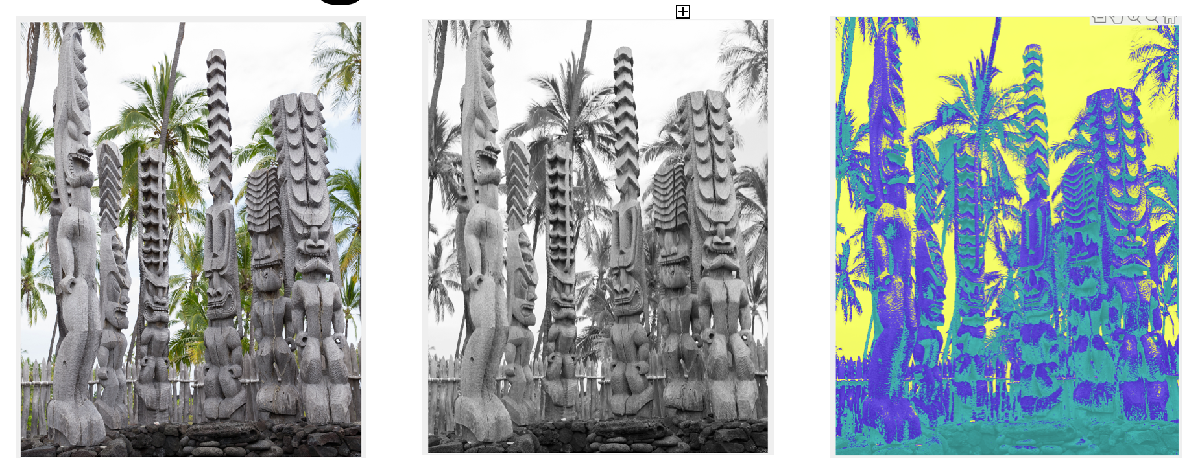

Original color image

Gray scale image

Gray scale segmentation. **Green palm trees leaves are segmented in the same class of foreground**. Colors can be used to distinguish palm tree leaves from tikis

There are few colors (gray foreground figures, green leaves, clear blu sky and white clouds).

Brightness can be ignored.

A and B dimensions of CIELAB color space can be used to distinguish leaves from tikis (ignoring L  brightness dimension)

clear
close all
a=imread('Tiki2.jpg');
lab_tiki = rgb2lab(a);
ab = lab_tiki(:,:,2:3);
ab = im2single(ab);
nColors = 4;
% repeat the clustering 3 times to avoid local minima
pixel_labels = imsegkmeans(ab,nColors,'NumAttempts',3);
% imshow(pixel_labels,[])
% title('Image Labeled by Cluster Index');
figure
mask1 = pixel_labels==1;
cluster1 = a .* uint8(mask1);
subplot(2,2,1)
imshow(cluster1)
title('Objects in Cluster 1');
subplot(2,2,2)
mask2 = pixel_labels==2;
cluster2 = a .* uint8(mask2);
imshow(cluster2)
title('Objects in Cluster 2');
subplot(2,2,3)
mask3 = pixel_labels==3;
cluster3 = a .* uint8(mask3);
imshow(cluster3)
title('Objects in Cluster 3');
subplot(2,2,4)
mask4 = pixel_labels==4;
cluster4 = a .* uint8(mask4);
imshow(cluster4)
title('Objects in Cluster 4');

# **Region Segmentation by Superpixels **

**slide 923 - 934**

**Superpixel** image would lead to the same description as the original, but by fewer basic elements (primitive units) compared to pixel in the original image.

Boundaries between regions of interest must be preserved in a superpixel image.

**Superpixels are generated approximately equal in size.**

**The initial superpixel centers, mi are obtained by sampling the image on a regular grid **spaced s units apart. 

Observations typically use 5-dimensional vectors containing three color components and two spatial coordinates.

cluster centers  are chosen  at regular grid intervals and moving them to a locations corresponding to the lowest gradient position in a 3×3 neighborhood (to avoid placing them at an edge )

Each pixel in the image is associated with the nearest cluster center whose search area overlaps this pixel.

After all the pixels are associated with the nearest cluster center, a new center is computed as the average labxy vector of all the pixels belonging to the cluster.

The process of associating pixels with the nearest cluster center and recomputing the cluster center is repeated until convergence. 

**Post-process the superpixel regions: **

Replace all the superpixels in each region, Ci, by their average value, mi .

`[`[`L`](https://it.mathworks.com/help/releases/R2024b/images/ref/superpixels.html?searchHighlight=superpixels&s_tid=doc_srchtitle#bu1_lcd-1-L)`,`[`numLabels`](https://it.mathworks.com/help/releases/R2024b/images/ref/superpixels.html?searchHighlight=superpixels&s_tid=doc_srchtitle#bu1_lcd-1-NumLabels)`] =` `superpixels``(`[`A`](https://it.mathworks.com/help/releases/R2024b/images/ref/superpixels.html?searchHighlight=superpixels&s_tid=doc_srchtitle#bu1_lcd-1-A)`,`[`N`](https://it.mathworks.com/help/releases/R2024b/images/ref/superpixels.html?searchHighlight=superpixels&s_tid=doc_srchtitle#bu1_lcd-1-N)`)` computes superpixels of the 2-D grayscale or RGB image `A`. `N` specifies the number of superpixels you want to create.

[`mask`](https://it.mathworks.com/help/releases/R2024b/images/ref/boundarymask.html?searchHighlight=boundarymask&s_tid=doc_srchtitle#bu1_me5-1-mask) `=` `boundarymask``(`[`L`](https://it.mathworks.com/help/releases/R2024b/images/ref/boundarymask.html?searchHighlight=boundarymask&s_tid=doc_srchtitle#bu1_me5-1-L)`)` computes a mask that represents the region boundaries for the input label matrix `L`. The output, `mask`, is a logical image that is `true` at boundary locations and `false` at non-boundary locations.

[`pixelIndexList`](https://it.mathworks.com/help/releases/R2024b/images/ref/label2idx.html?searchHighlight=label2idx&s_tid=doc_srchtitle#bu1_plo-1-pixelIndexList) `=` `label2idx``(`[`L`](https://it.mathworks.com/help/releases/R2024b/images/ref/label2idx.html?searchHighlight=label2idx&s_tid=doc_srchtitle#bu1_plo-1-L)`)` converts the regions described by the label matrix `L` into linear indices `pixelIndexList`.

clear
close all
A = imread('Tiki1.jpeg');
% A = imread('iceberg.tif');

A=rgb2gray(A);
[L,N] = superpixels(A,100);
%L is a label matrix of type double
% N is the requested number of superpixels

%Display the superpixel boundaries overlaid on the original image.
figure
BW = boundarymask(L);
imshow(imoverlay(A,BW,'cyan'))

% Set level of each pixel in output image to the mean gray level of the
% superpixel region.
idx = label2idx(L);
outputImage = zeros(size(A),'like',A);
% outputImage = zeros(size(A));

for labelVal = 1:N
        grayIdx = idx{labelVal};
        outputImage(grayIdx) = mean(A(grayIdx));
end
figure
imshow(outputImage)
colormap(gray(256))


%kmeans
[L,Centers] = imsegkmeans(outputImage,3);
B = labeloverlay(outputImage,L);
% B = labeloverlay(outputImage,L,'Transparency',0);
figure
imshow(B)
title('Labeled Image by kmeans')